# CE566 Final Project

## Attenuation Calculation

M = 7.5

M = 7.5000

R1 = 12

R1 = 12

R2 = 3

R2 = 3

V = 880

V = 880

[lny_m1,lny_sd1] = attenuation(M,R1,V)

lny_m1 = -1.3191

lny_sd1 = 0.5880

[lny_m2,lny_sd2] = attenuation(M,R2,V)

lny_m2 = -0.7521

lny_sd2 = 0.5880

% m1 = exp(lny_m1)
% m2 = exp(lny_m2)
% sd1 = exp(lny_sd1)
% sd2 = exp(lny_sd2)

## FORM

ccon1 = 1

ccon1 = 1

ccon2 = 0.9

ccon2 = 0.9000

ccon3 = 0.7

ccon3 = 0.7000

ccon4 = 0.57

ccon4 = 0.5700

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    0.000000e+00     3.203e+01     1.000e+00     0.000e+00     1.000e+00  
    1           6    1.364970e+01     0.000e+00     1.000e+00     1.365e+01     2.292e+02  
    2           9    8.253491e+00     0.000e+00     1.000e+00     5.536e+00     7.352e-01  
    3          12    6.101072e+00     0.000e+00     1.000e+00     2.219e+00     7.415e-01  
    4          15    5.606959e+00     0.000e+00     1.000e+00     4.991e-01     7.148e-01  
    5          18    5.503837e+00     0.000e+00     1.000e+00     1.245e-01     6.880e-01  
    6          21    5.106753e+00     0.000e+00     1.000e+00     5.497e-01     6.417e-01  
    7          24    3.788858e+00     0.000e+00     1.000e+00     2.575e+00     3.751e-01  
    8          27    3.692978e+00     0.000e+00     1.000e+00     1.613e+00     1.

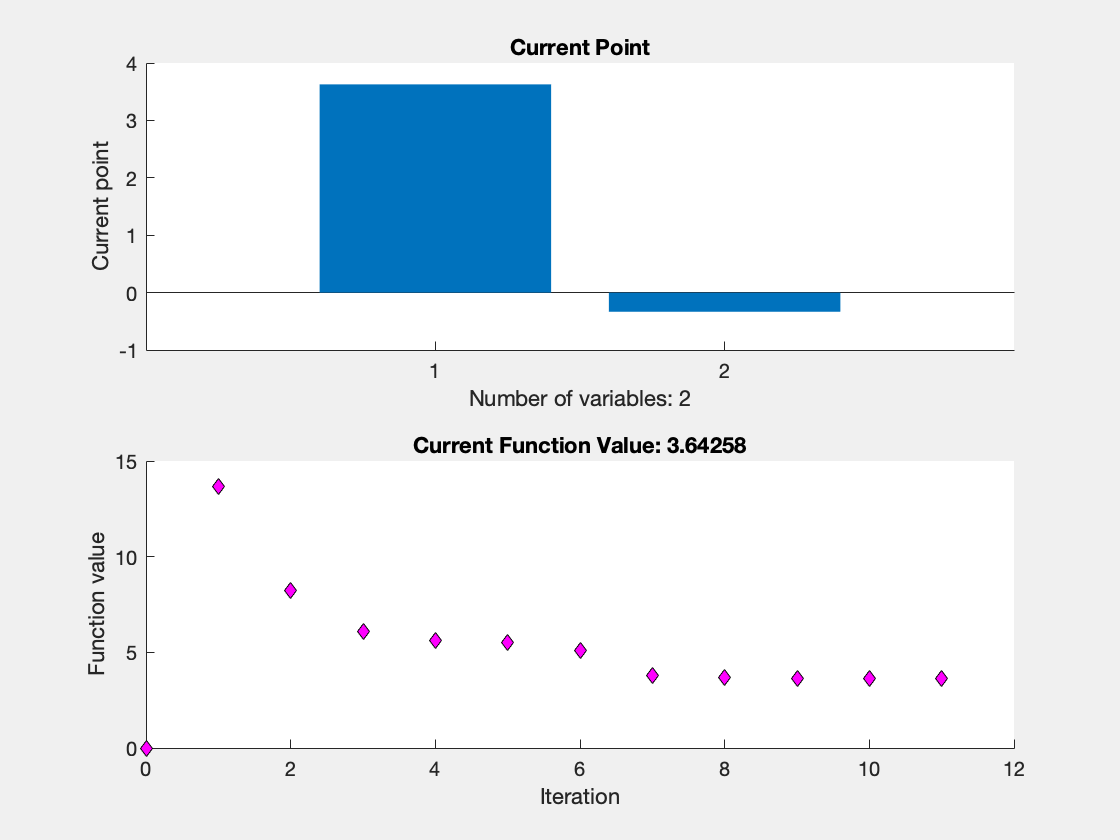


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% First-order reliability method
% Number of random variables, m
m = 2;

% Starting guess is u0 = 0
u0 = ones*zeros(1, m); 


% Minimize objective function
% exitflag = 1 for normal termination
options = optimset('Algorithm','sqp', 'Display','iter','PlotFcns',{@optimplotx,@optimplotfval});

[u1,fval1,exitflag1,output1] = fmincon(@objective,u0,[],[],[],[],[],[],@limitstate1,options);

%
% First-order reliability index
beta1 = fval1;
pf1 = normcdf(-beta1);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    0.000000e+00     2.923e+01     1.000e+00     0.000e+00     1.000e+00  
    1           6    1.246964e+01     0.000e+00     1.000e+00     1.247e+01     1.904e+02  
    2           9    7.569162e+00     0.000e+00     1.000e+00     5.020e+00     7.341e-01  
    3          12    5.654046e+00     0.000e+00     1.000e+00     1.965e+00     7.328e-01  
    4          15    5.238704e+00     0.000e+00     1.000e+00     4.171e-01     7.018e-01  
    5          18    5.127100e+00     0.000e+00     1.000e+00     1.416e-01     6.720e-01  
    6          21    4.667337e+00     0.000e+00     1.000e+00     6.548e-01     6.102e-01  
    7          24    3.474608e+00     0.000e+00     1.000e+00     2.987e+00     3.381e-01  
    8          27    3.459468e+00     0.000e+00     1.000e+00     2.257e-01     1.

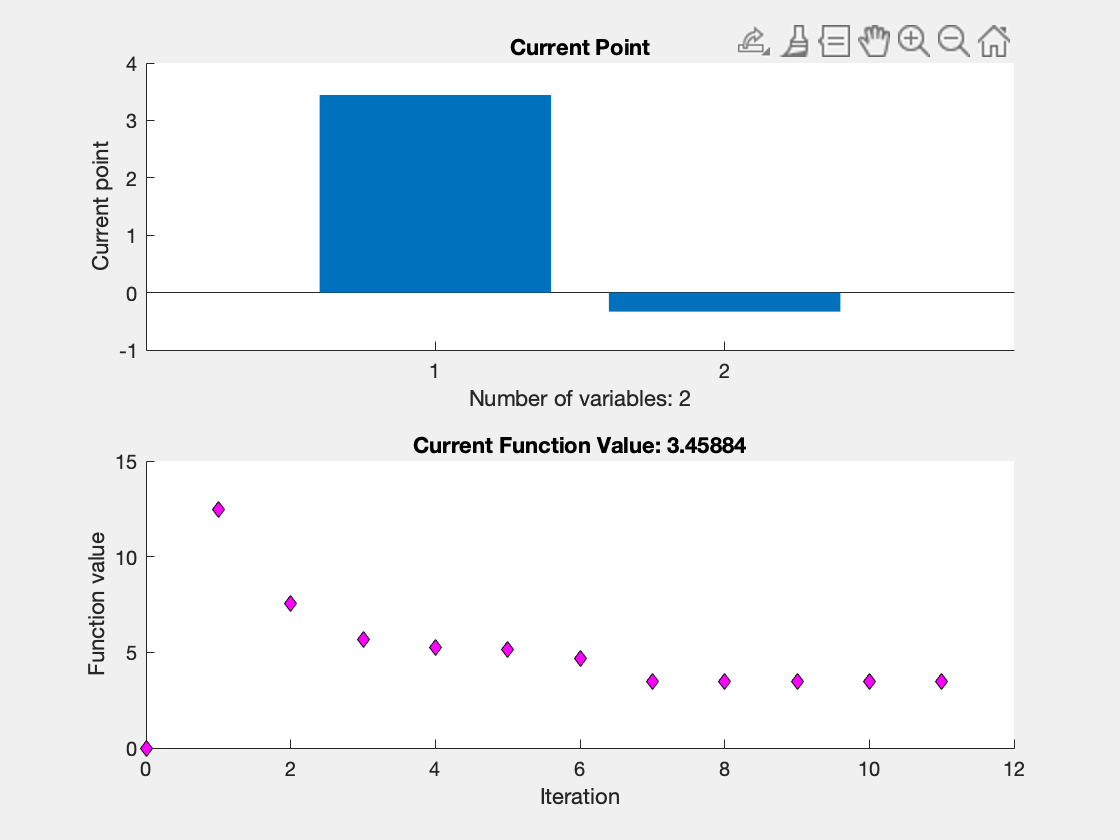


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[u2,fval2,exitflag2,output2] = fmincon(@objective,u0,[],[],[],[],[],[],@limitstate2,options);

%
% First-order reliability index
beta2 = fval2;
pf2 = normcdf(-beta2);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    0.000000e+00     2.363e+01     1.000e+00     0.000e+00     1.000e+00  
    1           6    1.011433e+01     0.000e+00     1.000e+00     1.011e+01     1.236e+02  
    2           9    6.205864e+00     0.000e+00     1.000e+00     3.988e+00     7.307e-01  
    3          12    4.768473e+00     0.000e+00     1.000e+00     1.461e+00     7.113e-01  
    4          15    4.497163e+00     0.000e+00     1.000e+00     2.716e-01     6.719e-01  
    5          18    4.344981e+00     0.000e+00     1.000e+00     2.091e-01     6.522e-01  
    6          21    3.707798e+00     0.000e+00     1.000e+00     1.001e+00     5.187e-01  
    7          24    3.585293e+00     0.000e+00     1.000e+00     3.925e+00     5.436e-01  
    8          27    3.069747e+00     0.000e+00     1.000e+00     1.869e+00     1.

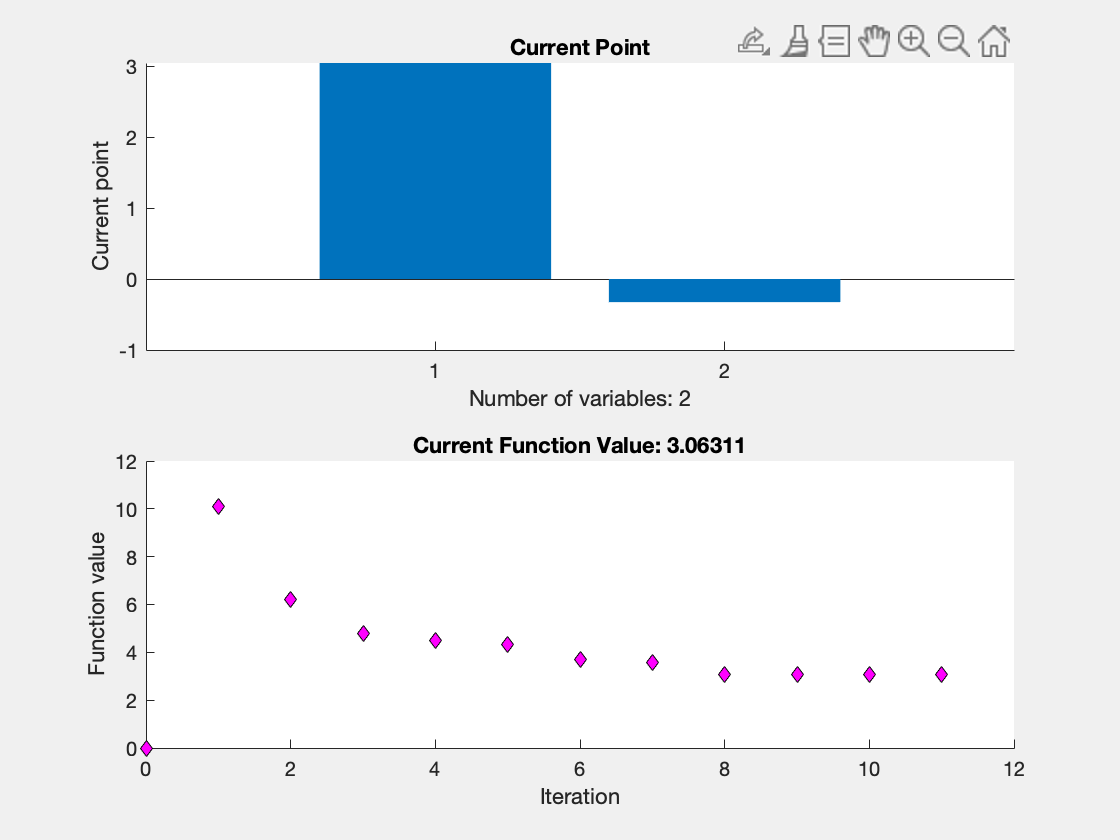


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[u3,fval3,exitflag3,output3] = fmincon(@objective,u0,[],[],[],[],[],[],@limitstate3,options);

%
% First-order reliability index
beta3 = fval3;
pf3 = normcdf(-beta3);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    0.000000e+00     1.999e+01     1.000e+00     0.000e+00     1.000e+00  
    1           6    8.588859e+00     0.000e+00     1.000e+00     8.589e+00     8.781e+01  
    2           9    5.326044e+00     0.000e+00     1.000e+00     3.318e+00     7.272e-01  
    3          12    4.200634e+00     0.000e+00     1.000e+00     1.136e+00     6.936e-01  
    4          15    4.009729e+00     0.000e+00     1.000e+00     1.938e-01     6.492e-01  
    5          18    3.815536e+00     0.000e+00     1.000e+00     2.771e-01     6.178e-01  
    6          21    3.075675e+00     0.000e+00     1.000e+00     1.316e+00     3.848e-01  
    7          24    2.923688e+00     0.000e+00     1.000e+00     2.191e+00     3.190e-01  
    8          27    2.782475e+00     0.000e+00     1.000e+00     9.064e-01     5.

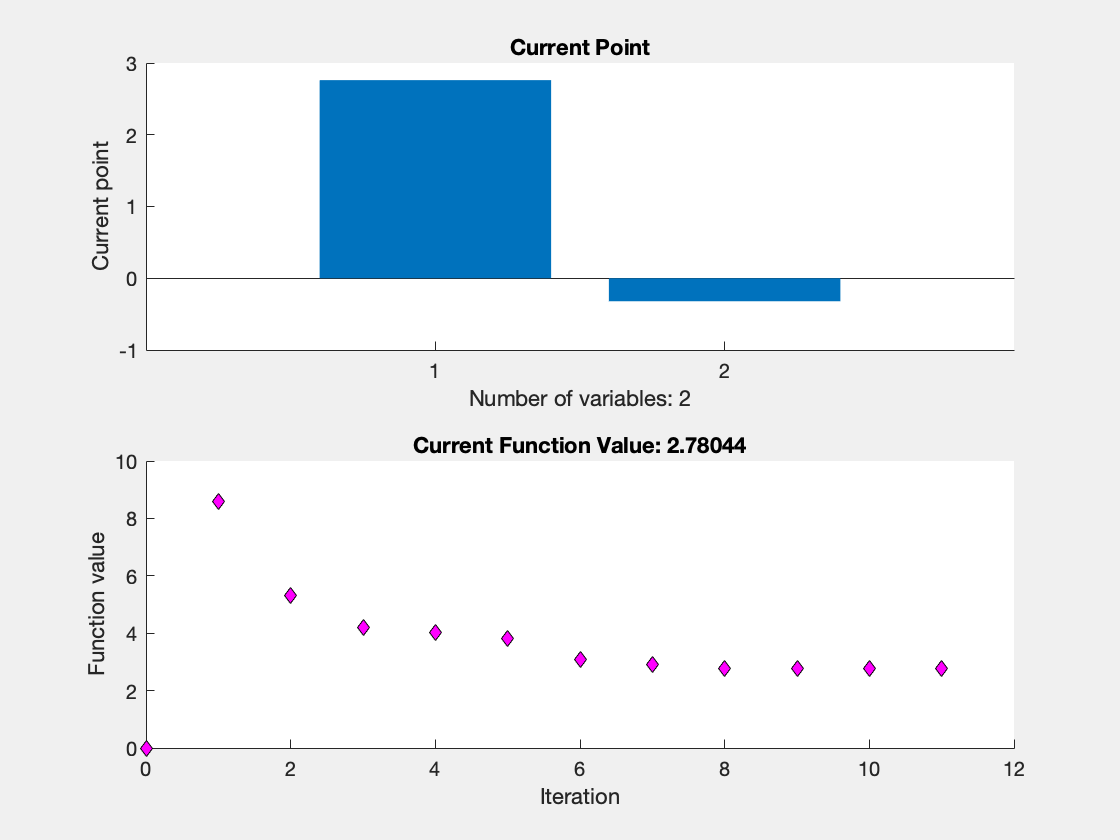


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[u4,fval4,exitflag4,output4] = fmincon(@objective,u0,[],[],[],[],[],[],@limitstate4,options);

%
% First-order reliability index
beta4 = fval4;
pf4 = normcdf(-beta4);

## CFP-FORM

T1 = [0.94 0.06 0 0;
    0 0.91 0.05 0.04;
    0 0 0.82 0.18;
    0 0 0 1]

T1 =     0.9400    0.0600         0         0
         0    0.9100    0.0500    0.0400
         0         0    0.8200    0.1800
         0         0         0    1.0000


T2 = [T1(1,:)*(1-pf1) pf1;
    T1(2,:)*(1-pf2) pf2;
    T1(3,:)*(1-pf3) pf3;
    T1(4,:)*(1-pf4) pf4;
    0 0 0 0 1]

T2 =     0.9399    0.0600         0         0    0.0001
         0    0.9098    0.0500    0.0400    0.0003
         0         0    0.8191    0.1798    0.0011
         0         0         0    0.9973    0.0027
         0         0         0         0    1.0000


## Markov Chain - System Failure Probability

n = 50

n = 50

pf = ones*zeros(1, n);
T3 = T2^n

T3 =     0.0450    0.0721    0.0274    0.7916    0.0639
         0    0.0088    0.0048    0.8878    0.0985
         0         0    0.0000    0.8808    0.1191
         0         0         0    0.8729    0.1271
         0         0         0         0    1.0000


pf(1)=T2(1,5)*T2(2,5)

pf = 	1.0e+-7 *

    0.3661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


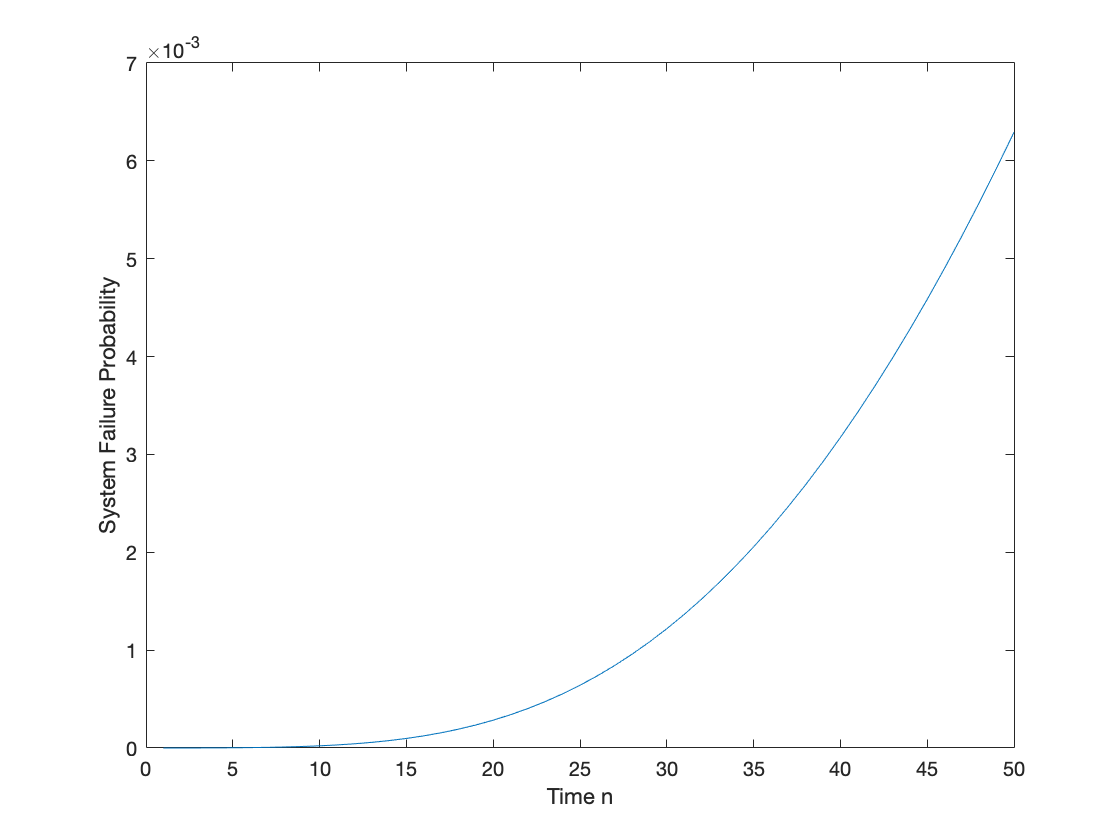

for i = 2:n
    x1 = T2(1,:)*T2^(i-1);
    x2 = T2(2,:)*T2^(i-1);
    pf(1,i)=x1(5)*x2(5);
end
plot(1:50,pf)
xlabel('Time n') 
ylabel('System Failure Probability')

## Fragility

cs = fragility_data(:,1);
cs1 = sortrows(fragility_data(cs==1, 2:3));
cs2 = sortrows(fragility_data(cs==2, 2:3));
cs3 = sortrows(fragility_data(cs==3, 2:3));
cs4 = sortrows(fragility_data(cs==4, 2:3));

IM1= cs1(:,1)%provide IM variable(s)

IM1 =     0.0754
    0.0978
    0.1291
    0.1908
    0.2064
    0.2143
    0.2426
    0.2527
    0.2771
    0.2973


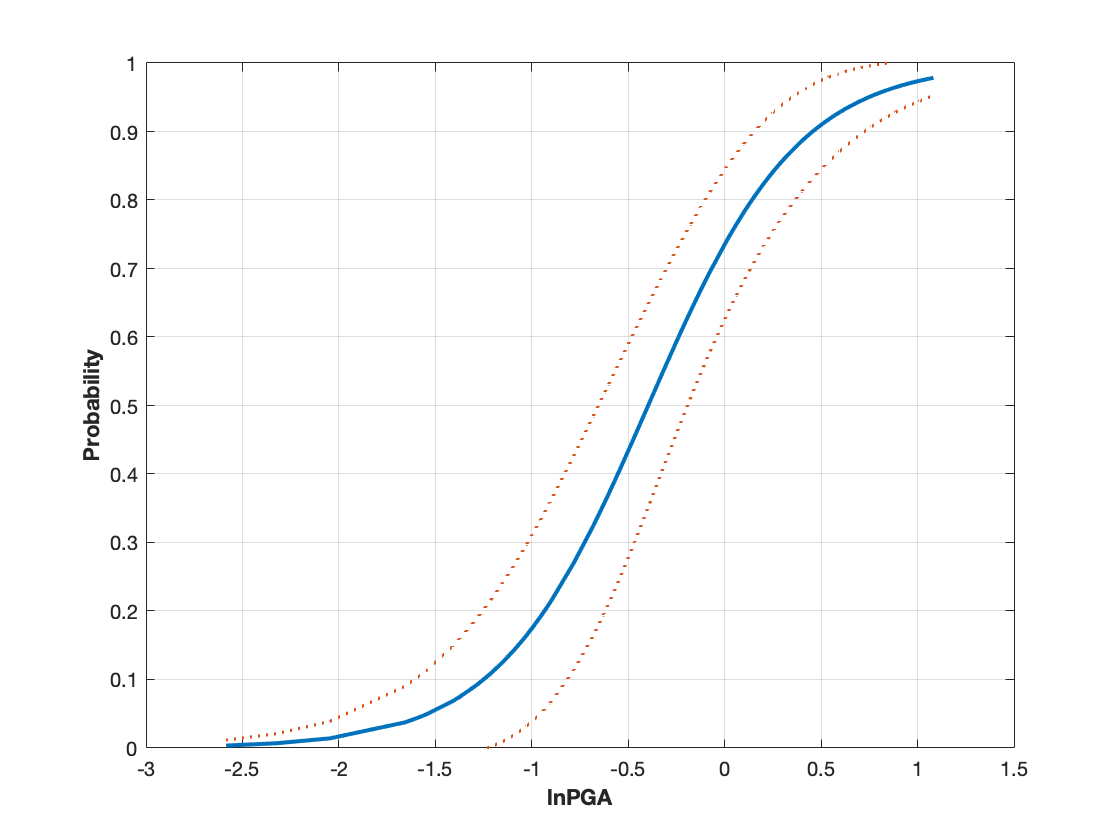

% Assign different condition states in X vector based on IM and provided data
X1 = cs1(:,2)+1;
    
    %--------------------------------NOMINAL-----------------------------------
[B_nominal1,~,stats1] = mnrfit(log(IM1),X1,'model','nominal');
[pihat_nominal1,dlow_nominal1,dhi_nominal1] = mnrval(B_nominal1,log(IM1),stats1,'type','cumulative','model','nominal','confidence',0.95);  
CIL_nominal1 = pihat_nominal1-dlow_nominal1;
CIH_nominal1 = pihat_nominal1+dhi_nominal1;
    
figure
hold('on');
plot(log(IM1),1-pihat_nominal1(:,1),'-','linewidth',2);
p = plot(log(IM1),1-CIL_nominal1(:,1),':','linewidth',1.0);
color = get(p, 'Color');
plot(log(IM1),1-CIH_nominal1(:,1),':','Color',color,'linewidth',1.0)
xlabel('lnPGA','FontWeight','bold','FontSize',11);
ylabel('Probability','FontWeight','bold','FontSize',11);
ylim([0 1]);
box('on');
grid('on');
hold('off');

## cs2

IM2= cs2(:,1)%provide IM variable(s)

IM2 =     0.0587
    0.1073
    0.1385
    0.1486
    0.1510
    0.1789
    0.1848
    0.2131
    0.2515
    0.2733


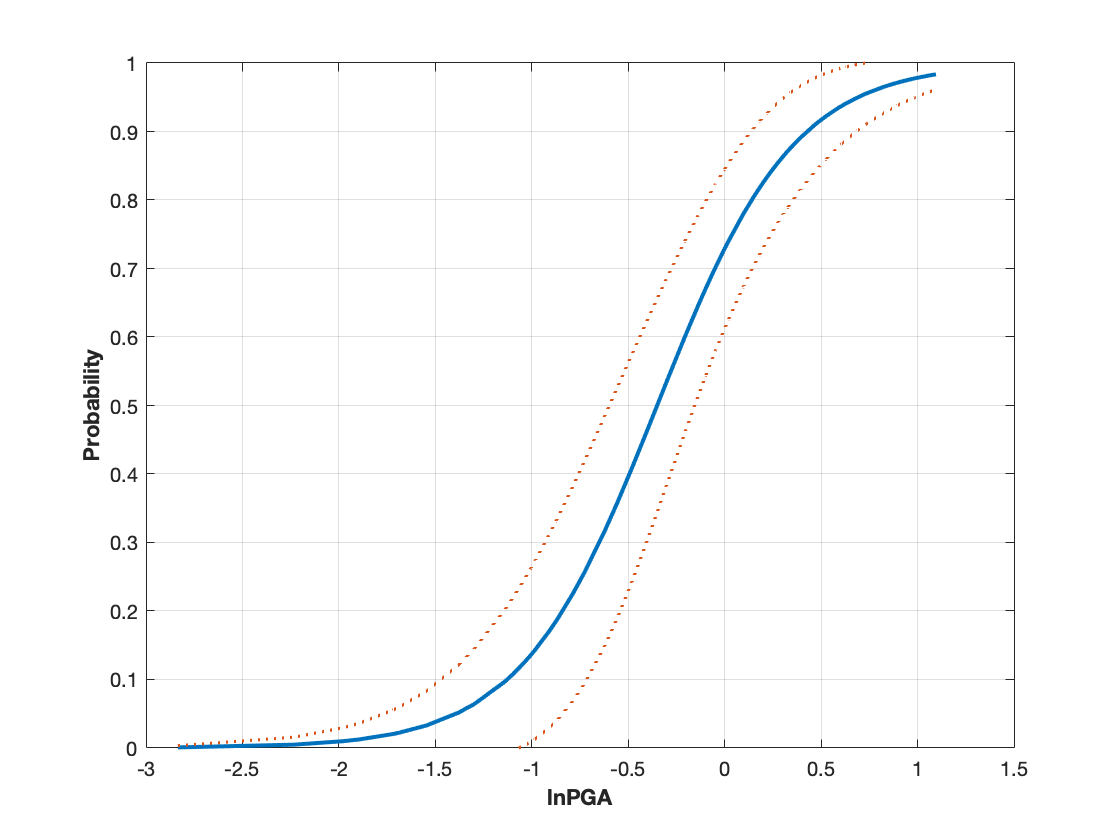

% Assign different condition states in X vector based on IM and provided data
X2 = cs2(:,2)+1;
    
    %--------------------------------NOMINAL-----------------------------------
[B_nominal2,~,stats2] = mnrfit(log(IM2),X2,'model','nominal');
[pihat_nominal2,dlow_nominal2,dhi_nominal2] = mnrval(B_nominal2,log(IM2),stats2,'type','cumulative','model','nominal','confidence',0.95);  
CIL_nominal2 = pihat_nominal2-dlow_nominal2;
CIH_nominal2 = pihat_nominal2+dhi_nominal2;
    
figure
hold('on');
plot(log(IM2),1-pihat_nominal2(:,1),'-','linewidth',2);
p = plot(log(IM2),1-CIL_nominal2(:,1),':','linewidth',1.0);
color = get(p, 'Color');
plot(log(IM2),1-CIH_nominal2(:,1),':','Color',color,'linewidth',1.0)
xlabel('lnPGA','FontWeight','bold','FontSize',11);
ylabel('Probability','FontWeight','bold','FontSize',11);
ylim([0 1]);
box('on');
grid('on');
hold('off');

## cs3

IM3= cs3(:,1)%provide IM variable(s)

IM3 =     0.0201
    0.0310
    0.0776
    0.0960
    0.1071
    0.1540
    0.1782
    0.1902
    0.2162
    0.2276


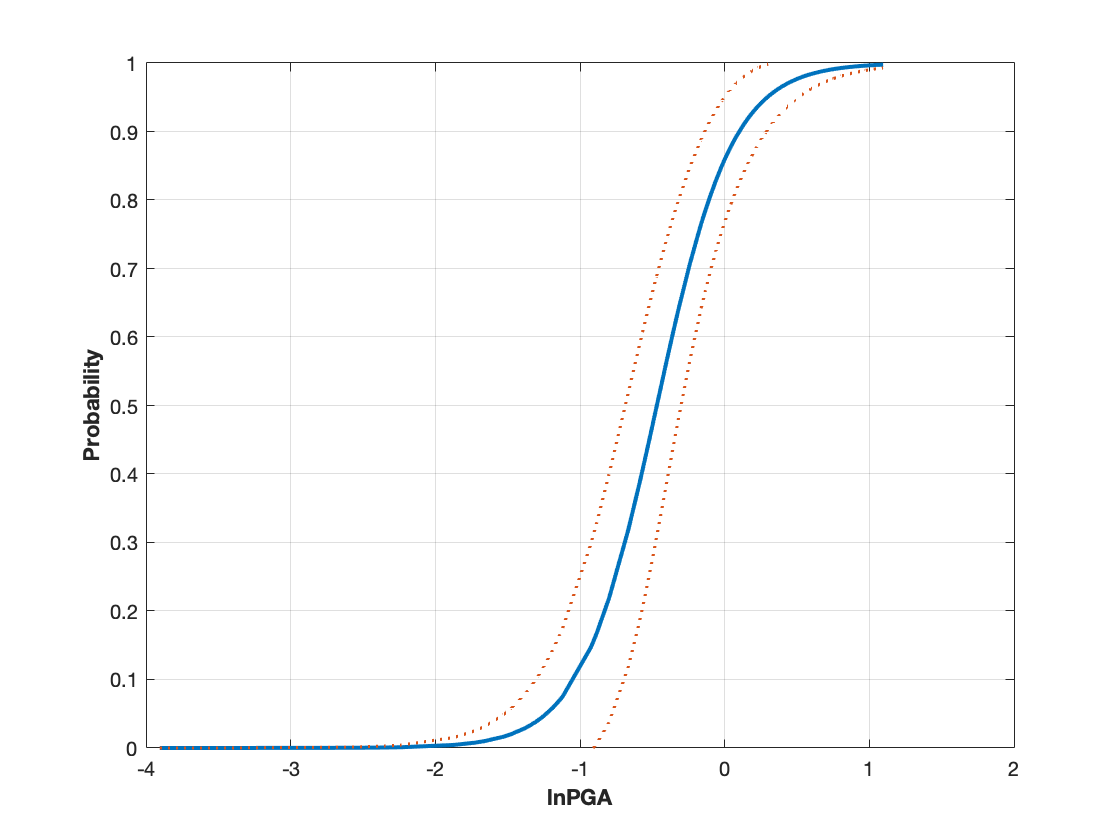

% Assign different condition states in X vector based on IM and provided data
X3 = cs3(:,2)+1;
    
    %--------------------------------NOMINAL-----------------------------------
[B_nominal3,~,stats3] = mnrfit(log(IM3),X3,'model','nominal');
[pihat_nominal3,dlow_nominal3,dhi_nominal3] = mnrval(B_nominal3,log(IM3),stats3,'type','cumulative','model','nominal','confidence',0.95);  
CIL_nominal3 = pihat_nominal3-dlow_nominal3;
CIH_nominal3 = pihat_nominal3+dhi_nominal3;
    
figure
hold('on');
plot(log(IM3),1-pihat_nominal3(:,1),'-','linewidth',2);
p = plot(log(IM3),1-CIL_nominal3(:,1),':','linewidth',1.0);
color = get(p, 'Color');
plot(log(IM3),1-CIH_nominal3(:,1),':','Color',color,'linewidth',1.0)
xlabel('lnPGA','FontWeight','bold','FontSize',11);
ylabel('Probability','FontWeight','bold','FontSize',11);
ylim([0 1]);
box('on');
grid('on');
hold('off');

## cs4

IM4= cs4(:,1)%provide IM variable(s)

IM4 =     0.0469
    0.0545
    0.0578
    0.0877
    0.1033
    0.1269
    0.1580
    0.1644
    0.1814
    0.2144


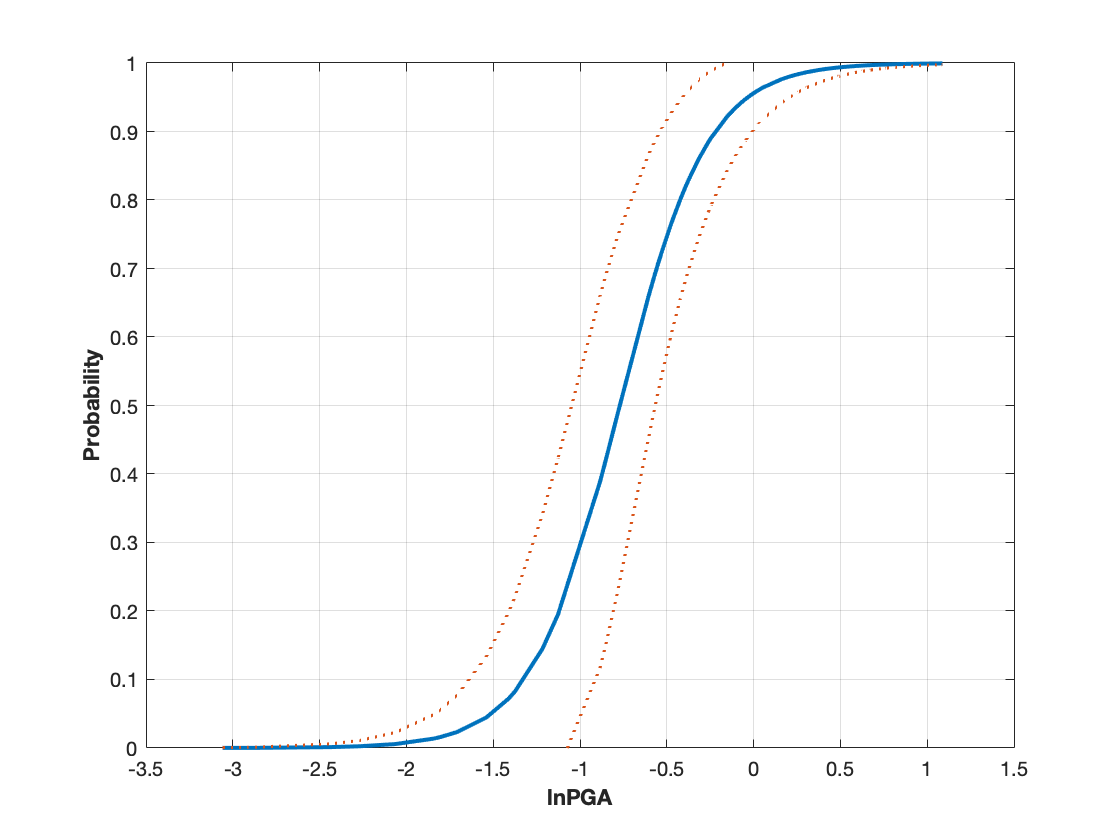

% Assign different condition states in X vector based on IM and provided data
X4 = cs4(:,2)+1;
    
    %--------------------------------NOMINAL-----------------------------------
[B_nominal4,~,stats4] = mnrfit(log(IM4),X4,'model','nominal');
[pihat_nominal4,dlow_nominal4,dhi_nominal4] = mnrval(B_nominal4,log(IM4),stats4,'type','cumulative','model','nominal','confidence',0.95);  
CIL_nominal4 = pihat_nominal4-dlow_nominal4;
CIH_nominal4 = pihat_nominal4+dhi_nominal4;
    
figure
hold('on');
plot(log(IM4),1-pihat_nominal4(:,1),'-','linewidth',2);
p = plot(log(IM4),1-CIL_nominal4(:,1),':','linewidth',1.0);
color = get(p, 'Color');
plot(log(IM4),1-CIH_nominal4(:,1),':','Color',color,'linewidth',1.0)
xlabel('lnPGA','FontWeight','bold','FontSize',11);
ylabel('Probability','FontWeight','bold','FontSize',11);
ylim([0 1]);
box('on');
grid('on');
hold('off');

## Monte Carlo

n1 = 10^4

n = 10000

lnPGA1 = normrnd(lny_m1,lny_sd1,n1,1)

lnPGA1 =    -1.7802
   -1.0328
   -1.9186
   -0.5818
   -1.6525
   -1.3217
   -1.7113
   -1.9476
   -1.5343
   -1.9277


lnPGA2 = normrnd(lny_m2,lny_sd2,n1,1)

lnPGA2 =    -1.6814
    0.1861
   -0.4555
   -0.3471
   -0.6976
   -0.3139
   -1.7341
   -0.0313
   -1.0878
   -0.8196


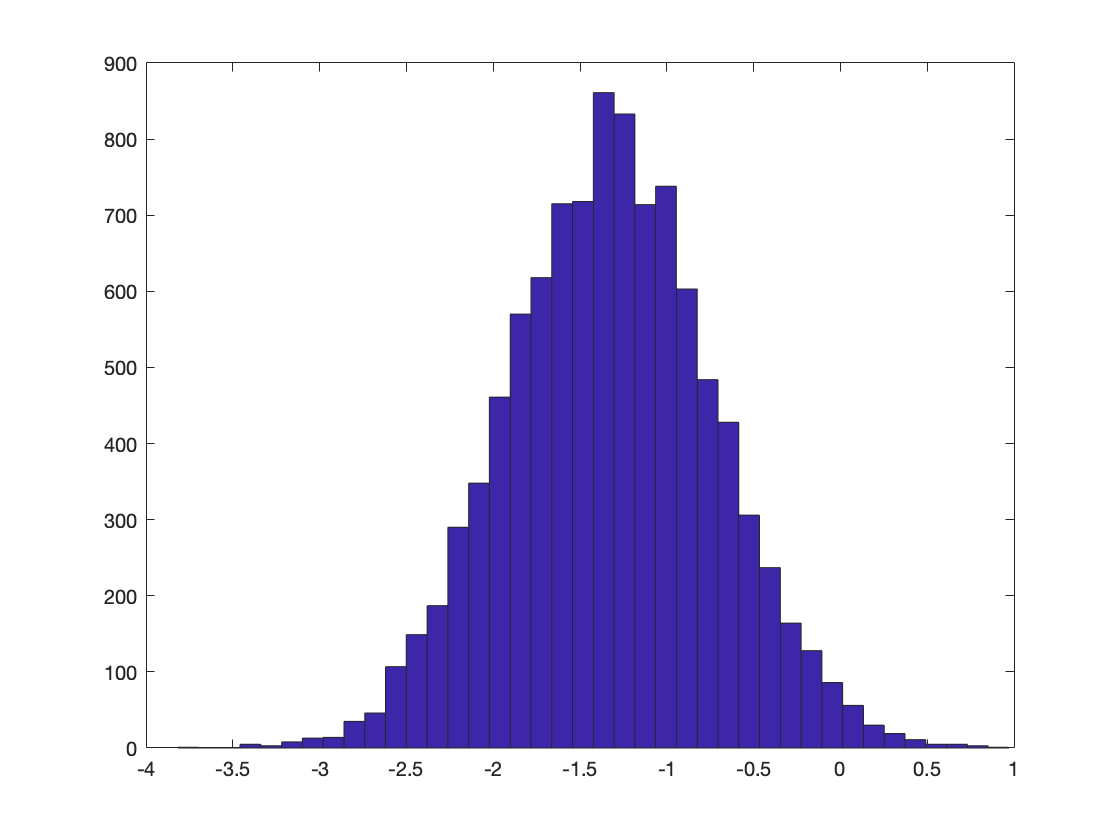

hist(lnPGA1,40)

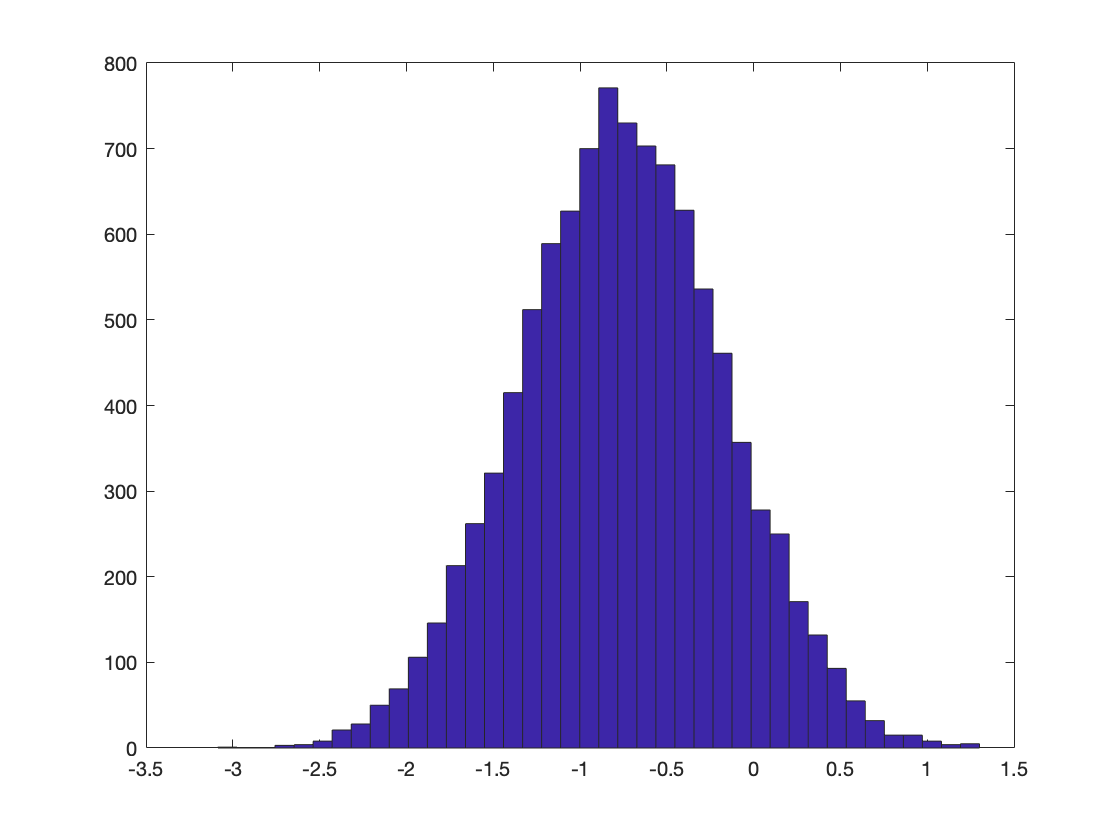

hist(lnPGA2,40)

## prob

[pihat_nominal11,dlow_nominal11,dhi_nominal11] = mnrval(B_nominal1,lnPGA1,stats1,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal12,dlow_nominal12,dhi_nominal12] = mnrval(B_nominal2,lnPGA1,stats2,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal13,dlow_nominal13,dhi_nominal13] = mnrval(B_nominal3,lnPGA1,stats3,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal14,dlow_nominal14,dhi_nominal14] = mnrval(B_nominal4,lnPGA1,stats4,'type','cumulative','model','nominal','confidence',0.95);

[pihat_nominal21,dlow_nominal21,dhi_nominal21] = mnrval(B_nominal1,lnPGA2,stats1,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal22,dlow_nominal22,dhi_nominal22] = mnrval(B_nominal2,lnPGA2,stats2,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal23,dlow_nominal23,dhi_nominal23] = mnrval(B_nominal3,lnPGA2,stats3,'type','cumulative','model','nominal','confidence',0.95);
[pihat_nominal24,dlow_nominal24,dhi_nominal24] = mnrval(B_nominal4,lnPGA2,stats4,'type','cumulative','model','nominal','confidence',0.95);

p11 = 1-mean(pihat_nominal11)

p11 = 0.1499

p12 = 1-mean(pihat_nominal12)

p12 = 0.1274

p13 = 1-mean(pihat_nominal13)

p13 = 0.1265

p14 = 1-mean(pihat_nominal14)

p14 = 0.2255


p21 = 1-mean(pihat_nominal21)

p21 = 0.3418

p22 = 1-mean(pihat_nominal22)

p22 = 0.3151

p23 = 1-mean(pihat_nominal23)

p23 = 0.3490

p24 = 1-mean(pihat_nominal24)

p24 = 0.5077

ps = [p11 p12 p13 p14;
    p21 p22 p23 p24]

ps =     0.1499    0.1274    0.1265    0.2255
    0.3418    0.3151    0.3490    0.5077


## Poisson

lambda = 0.02

lambda = 0.0200

pp = lambda*exp(-lambda)

pp = 0.0196

pas = ps*pp

pas =     0.0029    0.0025    0.0025    0.0044
    0.0067    0.0062    0.0068    0.0100


pn = 1-pp

pn = 0.9804

pno = 1-pas

pno =     0.9971    0.9975    0.9975    0.9956
    0.9933    0.9938    0.9932    0.9900


T14 = [T2(1,1:4)*pno(1,1) 1-sum(T2(1,1:4)*pno(1,1));
    T2(2,1:4)*pno(1,2) 1-sum(T2(2,1:4)*pno(1,2));
    T2(3,1:4)*pno(1,3) 1-sum(T2(3,1:4)*pno(1,3));
    T2(4,1:4)*pno(1,4) 1-sum(T2(4,1:4)*pno(1,4));
    0 0 0 0 1]

T14 =     0.9371    0.0598         0         0    0.0031
         0    0.9075    0.0499    0.0399    0.0028
         0         0    0.8171    0.1794    0.0036
         0         0         0    0.9929    0.0071
         0         0         0         0    1.0000



T24 = [T2(1,1:4)*pno(2,1) 1-sum(T2(1,1:4)*pno(2,1));
    T2(2,1:4)*pno(2,2) 1-sum(T2(2,1:4)*pno(2,2));
    T2(3,1:4)*pno(2,3) 1-sum(T2(3,1:4)*pno(2,3));
    T2(4,1:4)*pno(2,4) 1-sum(T2(4,1:4)*pno(2,4));
    0 0 0 0 1]

T24 =     0.9336    0.0596         0         0    0.0068
         0    0.9041    0.0497    0.0397    0.0064
         0         0    0.8135    0.1786    0.0079
         0         0         0    0.9874    0.0126
         0         0         0         0    1.0000


## Markov Chain

n = 50

n = 50

pf5 = ones*zeros(1, n);
pf5(1)=T14(1,5)*T24(2,5)

pf5 = 	1.0e+-4 *

    0.1982         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


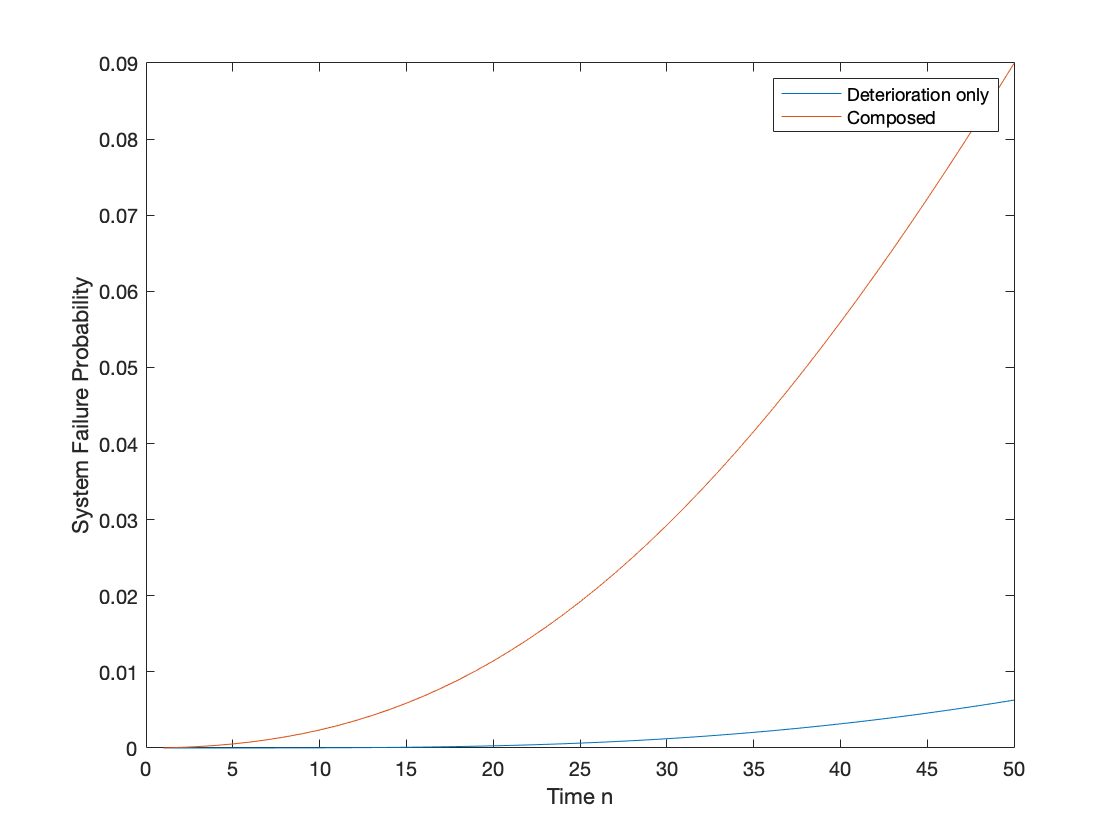

for i = 2:n
    x3 = T14(1,:)*T14^(i-1);
    x4 = T24(2,:)*T24^(i-1);
    pf5(1,i)=x3(5)*x4(5);
end
plot(1:50,pf, 1:50, pf5)
xlabel('Time n') 
ylabel('System Failure Probability')
legend('Deterioration only','Composed')

## MDP

% MDP with 25 states and 4 actions.
%Transition probabilities for do nothing
T6 = kron(T14,T24)

T6 =     0.8749    0.0558         0         0    0.0064    0.0558    0.0036         0         0    0.0004         0         0         0         0         0         0         0         0         0         0    0.0029    0.0002         0         0    0.0000
         0    0.8473    0.0466    0.0372    0.0060         0    0.0541    0.0030    0.0024    0.0004         0         0         0         0         0         0         0         0         0         0         0    0.0028    0.0002    0.0001    0.0000
         0         0    0.7623    0.1673    0.0074         0         0    0.0487    0.0107    0.0005         0         0         0         0         0         0         0         0         0         0         0         0    0.0025    0.0005    0.0000
         0         0         0    0.9253    0.0118         0         0         0    0.0591    0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0030  

T5 = zeros(5,5)

T5 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


T5(:,1)=1

T5 =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


T7 = kron(T5,T24) % Repair Component 1

T7 =     0.9336    0.0596         0         0    0.0068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.9041    0.0497    0.0397    0.0064         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8135    0.1786    0.0079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.9874    0.0126         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

T8 = kron(T14,T5)

T8 =     0.9371         0         0         0         0    0.0598         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0031         0         0         0         0
    0.9371         0         0         0         0    0.0598         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0031         0         0         0         0
    0.9371         0         0         0         0    0.0598         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0031         0         0         0         0
    0.9371         0         0         0         0    0.0598         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0031         0         0         0  

T9 = kron(T5,T5)%Transition probabilities for repair

T9 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     


gamma = .95; % discount factor  
c_s= zeros(1, 25);
c_s(1,25) = 50000% state cost

c_s =            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0       50000


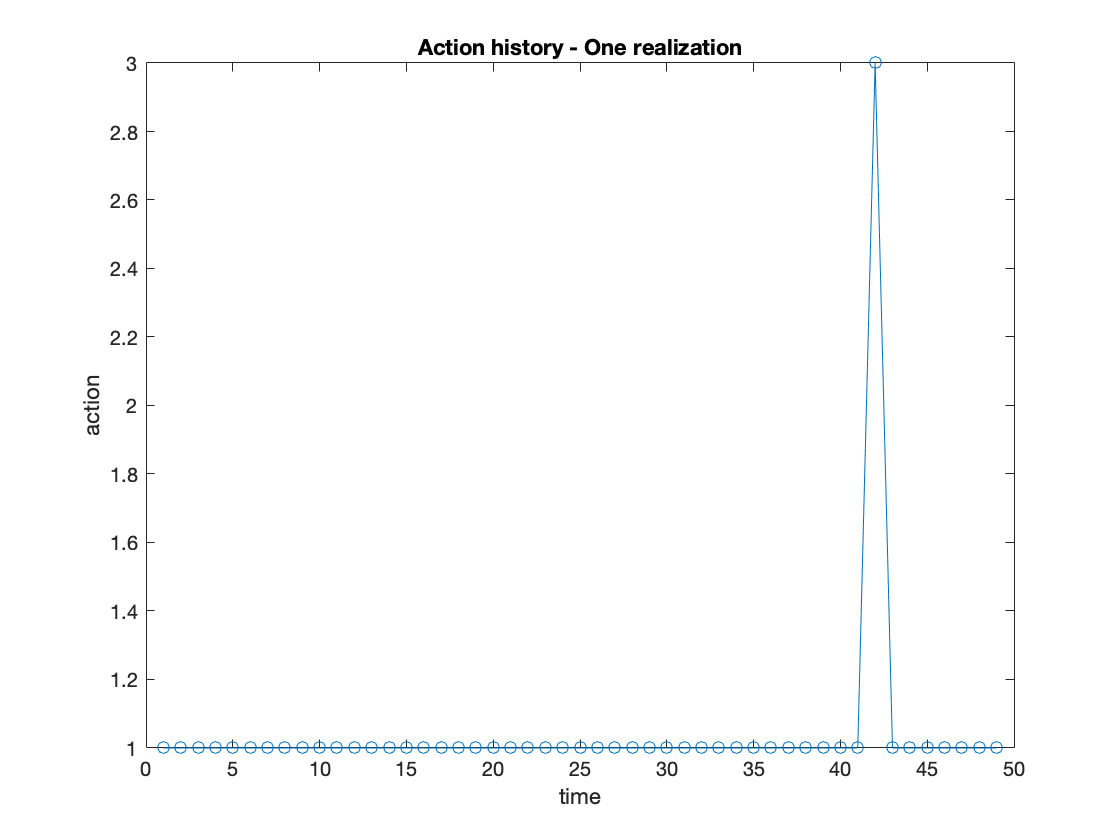

c_a= [0 80 100 140]; % action cost
horizon=50;  % total steps

% value iteration (based on Q-values)
V = zeros(25,horizon+1);
for i = horizon:-1:1
    for st = 1:25
        Q1 = c_s(st) + c_a(1) + gamma*T6(st,:)*V(:,i+1); % Q value of action 1
        Q2 = c_s(st) + c_a(2) + gamma*T7(st,:)*V(:,i+1); % Q value of action 2
        Q3 = c_s(st) + c_a(3) + gamma*T8(st,:)*V(:,i+1);
        Q4 = c_s(st) + c_a(4) + gamma*T9(st,:)*V(:,i+1);
        [V(st,i),policy(st,i)] = min([Q1;Q2;Q3;Q4]); % minQ
    end
end


%Realization
s(1) = 2; %initial state
rng(1) % set random seed to reproduce simulation/plots

for t=2:horizon
    a(t-1) = policy(s(t-1),t-1);
   % a(t-1) = 1; %uncontrolled
    if a(t-1)==1
        s(t)=randsample(1:25,1,true,T6(s(t-1),:));
    elseif a(t-1)==2
        s(t)=randsample(1:25,1,true,T7(s(t-1),:));
    elseif a(t-1)==3
        s(t)=randsample(1:25,1,true,T8(s(t-1),:));
    else
        s(t)=randsample(1:25,1,true,T9(s(t-1),:));
    end
end

figure (1)       
plot(a,'-o')
title('Action history - One realization')
xlabel('time')
ylabel('action')

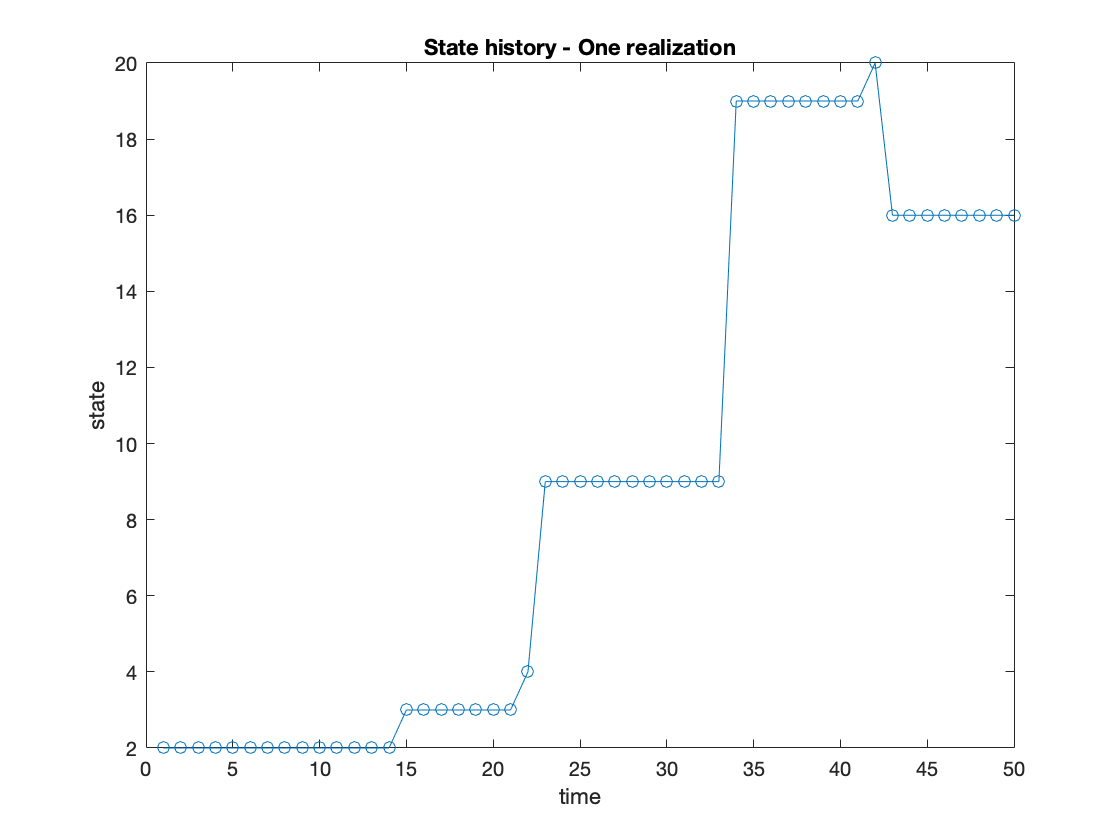


% figure(2)
plot(s,'-o')
title('State history - One realization')
xlabel('time')
ylabel('state')

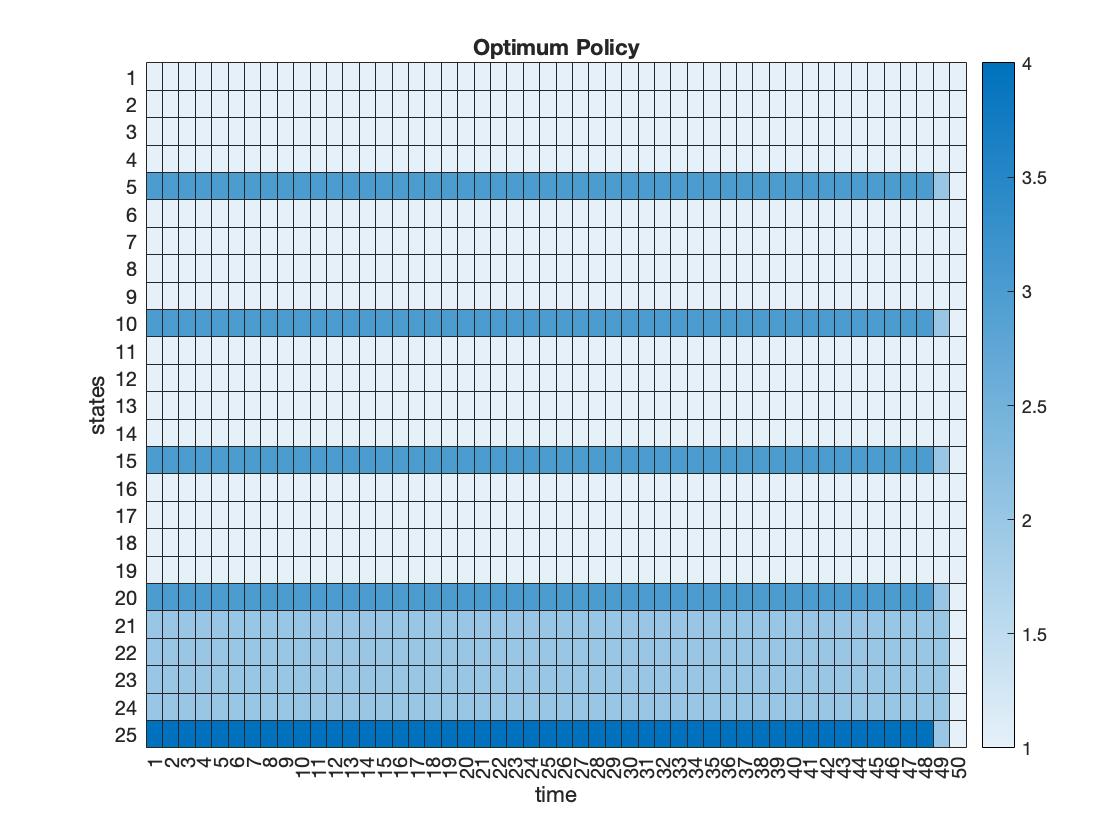


figure(3)
heatmap(policy)
colorbar
title('Optimum Policy')
xlabel('time')
ylabel('states')

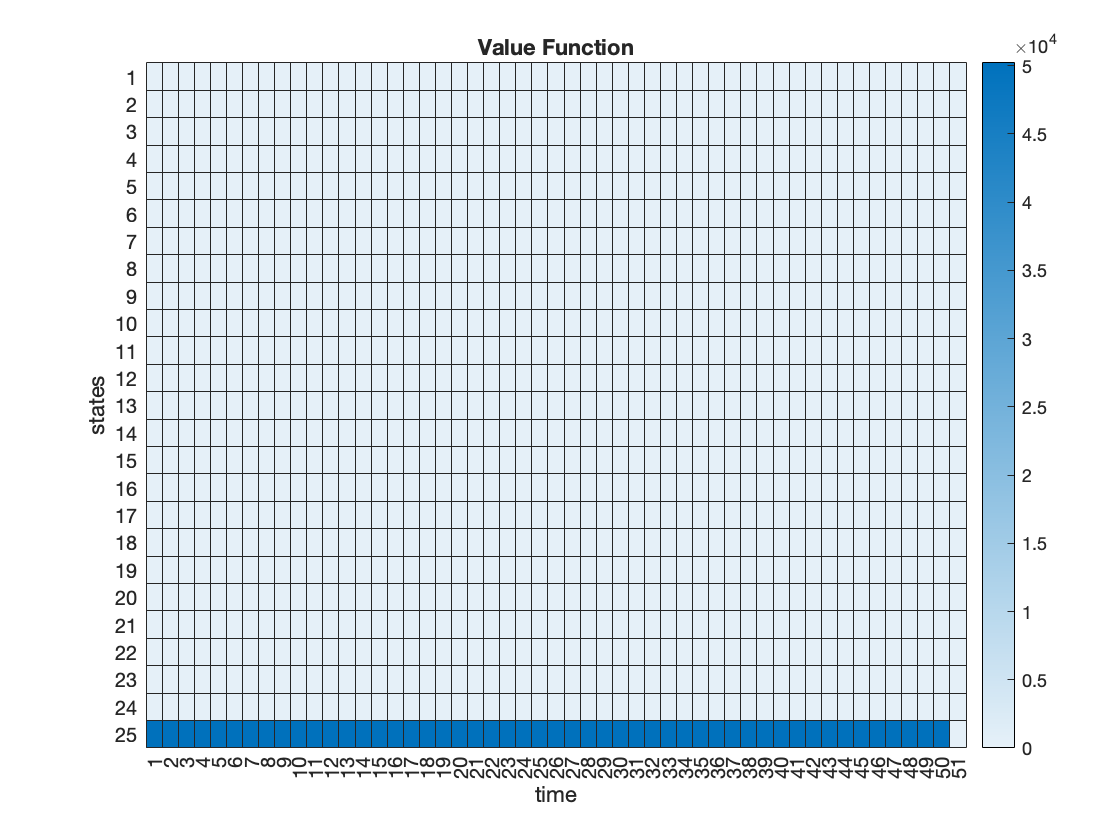


figure(4)
heatmap(V)
colorbar
title('Value Function')
xlabel('time')
ylabel('states')

## System failure probability

n = 50

n = 50

pf6 = pf5

pf6 =     0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0015    0.0019    0.0024    0.0029    0.0036    0.0043    0.0050    0.0059    0.0068    0.0078    0.0090    0.0101    0.0114    0.0128    0.0143    0.0158    0.0175    0.0192    0.0210    0.0230    0.0250    0.0271    0.0293    0.0316    0.0339    0.0364    0.0389    0.0416    0.0443    0.0471    0.0500    0.0529    0.0559    0.0590    0.0622    0.0655    0.0688    0.0721    0.0756    0.0791    0.0827    0.0863    0.0900


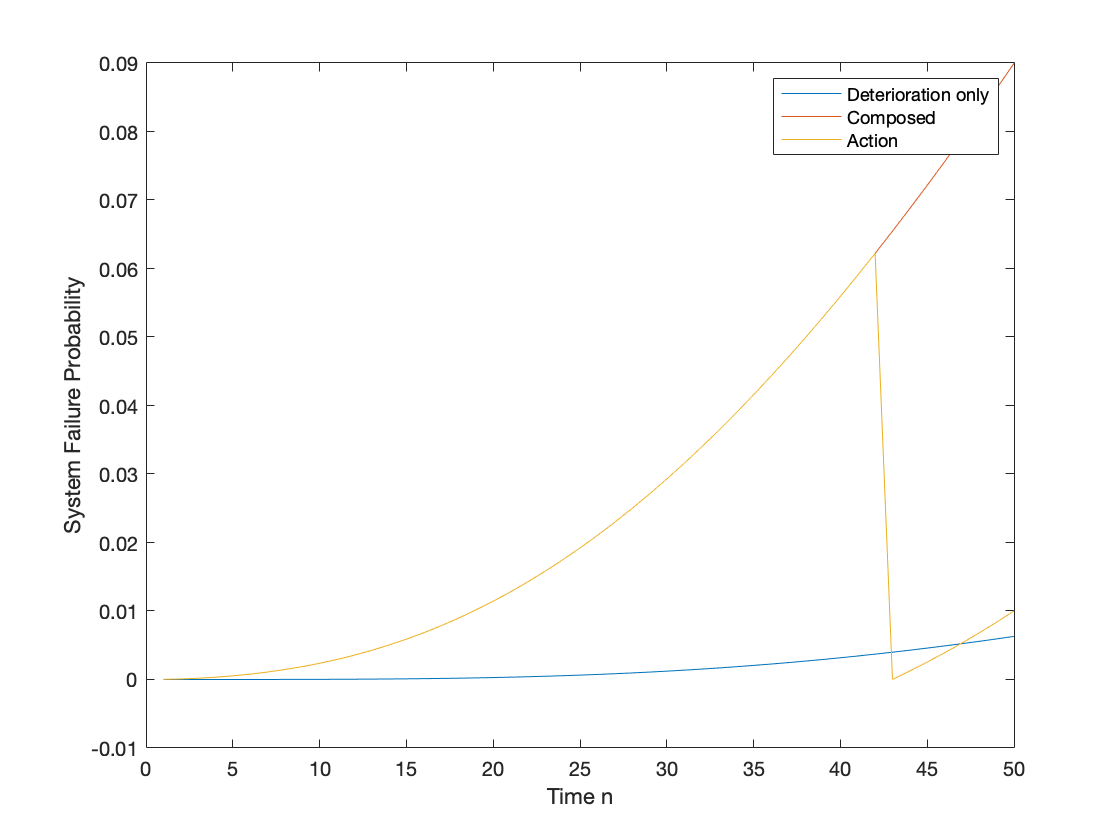

for i = 43:n
    x5 = T14(1,:)*T14^(i-1);
    x6 = T24(1,:)*T24^(i-44);
    pf6(1,i)=x5(5)*x6(5);
end
plot(1:50,pf, 1:50, pf5,1:50,pf6)
xlabel('Time n') 
ylabel('System Failure Probability')
legend('Deterioration only','Composed','Action')

## CBM

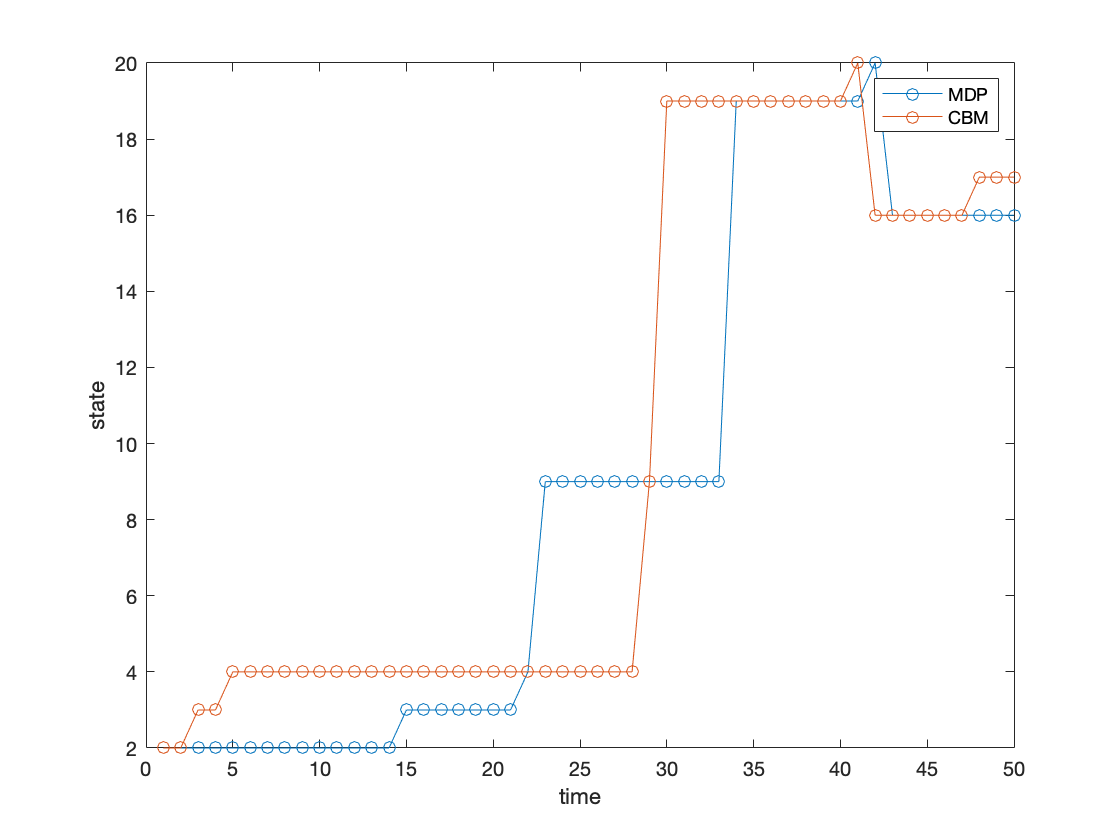

%Realization
s1(1) = 2; %initial state
rng(5)% set random seed to reproduce simulation/plots

for t=2:horizon
    a(t-1) = policy(s1(t-1),t-1);
   % a(t-1) = 1; %uncontrolled
    if a(t-1)==1
        s1(t)=randsample(1:25,1,true,T6(s1(t-1),:));
    elseif a(t-1)==2
        s1(t)=randsample(1:25,1,true,T7(s1(t-1),:));
    elseif a(t-1)==3
        s1(t)=randsample(1:25,1,true,T8(s1(t-1),:));
    else
        s1(t)=randsample(1:25,1,true,T9(s1(t-1),:));
    end
end

plot(1:50,s,'-o',1:50,s1,'-o')
xlabel('time')
ylabel('state')
legend('MDP','CBM')

## Functions

function [lny_m,lny_sd] = attenuation(M,R,V)

%Based on the paper:
%Kenneth W. Campbell and Yousef Bozorgnia, "NGA-West2 Ground Motion Model for the 
%Average Horizontal Components of PGA, PGV, and 5% Damped Linear Acceleration Response Spectra", 
%Earthquake Spectra, Volume 30, No. 3, pages 1087–1115, 2014.

%only for M>6.5; V>865m/s

%model parameters of NGA West-2
c0= -4.416 ; c1= .984; c2=0.537 ;
c3=-1.499 ; c4=-.496 ; c5=-2.773 ; c6=.248 ;
c7 =6.768 ; c11=1.090; k1=865 ; k2=-1.186 ; n=1.18 ;

f_mag = c0+c1*M+c2*(M-4.5)+c3*(M-5.5)+c4*(M-6.5); %magnitude term
f_dist = (c5+c6*M)*log(sqrt(R^2+c7^2)); %distance from source term
f_soil = (c11 + k2*n)*log(V/k1); %soil conditions term
%Note: original NGA West-2 model has more terms that are considered 0 here

lny_m = f_mag+f_dist+f_soil; % lnPGA - mean value of normal
lny_sd = sqrt(.322^2+.492^2); % standard deviation of lnPGA random variable
end

function [c, ceq] = limitstate1(u)
%
% Convert standard normal random variables to physical variables
%

x1 = 2*u(1)+1;
x2 = 1.5*u(2)+4;

% Inequality constraints, c < 0
c = 28-0.47*x1^2+0.95*x2+0.7;

% Equality constraints
ceq = [];

end
function [c, ceq] = limitstate2(u)
%
% Convert standard normal random variables to physical variables
%

x1 = 2*u(1)+1;
x2 = 1.5*u(2)+4;

% Inequality constraints, c < 0
c = 28*0.9-0.47*x1^2+0.95*x2+0.7;

% Equality constraints
ceq = [];

end
function [c, ceq] = limitstate3(u)
%
% Convert standard normal random variables to physical variables
%

x1 = 2*u(1)+1;
x2 = 1.5*u(2)+4;

% Inequality constraints, c < 0
c = 28*0.7-0.47*x1^2+0.95*x2+0.7;

% Equality constraints
ceq = [];

end
function [c, ceq] = limitstate4(u)
%
% Convert standard normal random variables to physical variables
%

x1 = 2*u(1)+1;
x2 = 1.5*u(2)+4;

% Inequality constraints, c < 0
c = 28*0.57-0.47*x1^2+0.95*x2+0.7;

% Equality constraints
ceq = [];

end
% Objective function for FORM

function f = objective(u)
% 
% Objective function = distance from the origin, beta

f = norm(u);

end
% pause(1/15)
